# **Lab 5. Prefiltering effects on the identification**

Through this lab we will assess the prefiltering effects on the identification based on the prediction error.

## 1. Identification without prefiltering

We first consider the identification process of an ARX system without performing the prefiltering of the input and the output, in order to highlight the magnitude of the error at low frequencies.

clc, clearvars, close all

### 1.1. Defining the system

We first choose the sampling time and the number of data.

% Sampling time
Ts = 1;

% Number of data
N = 500;

Then we declare the polynomials `A` and `B` of the system, in order to compute the transfer function.

% ARX polynomials
A0 = [1.0, -1.5, 0.7];
B0 = [0.0,  1.0, 0.5];

% Transfer function
G0 = tf(B0,A0,Ts);

Finally we define a random input vector and we compute the corresponding output.

% Random input
U = randn(N,1);

% Output
Y0 = filter(B0,A0,U);

### 1.2. Introducing white noise

Since the output of the system is ideal, because no noise was considered, we introduce the white noise vector. Then we normalize the noise vector considering a noise power of 10%, so a standard deviation of 0.1, and then we add it to the output vector.

% White noise
wn = randn(N,1);

% White noise normalization
wn = wn/std(wn)*std(Y0)*sqrt(0.1);

% Noisy output
Yw = Y0 + wn;

Now that we have computed the output of the system under uncertainty, we can define our `iddata` object.

% Dataset
Dw = iddata(Yw,U);

### 1.3. Performing identification

We can perform the identification of the system using an ARX(2,2) model, so a model that belongs to the same family of the system.

% ARX(2,2) model
mw = arx(Dw,[2,2,1]);

Then we can evaluate the behaviour of the model using the `compare` command.

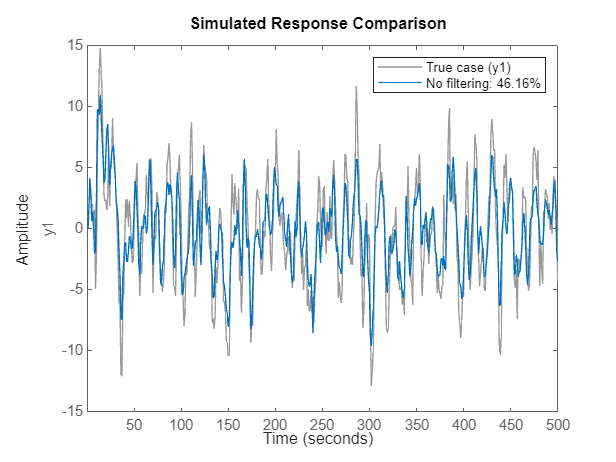

% Plotting results
figure(1), compare(Dw,mw),
legend("True case","No filtering")

As we can see the results are not that good. Also, we can't understand if we committed a bigger error at low or at high frequencies.

### 1.4. Checking Bode diagram

Since in time domain it is not possible to understand where the mistake is (of course there are many tools like the whiteness test but they are not very useful in this case), we look at the frequency domain. In particular we compare the Bode diagrams of the original system, the one to be identified, and the Bode diagrams of the identified model.

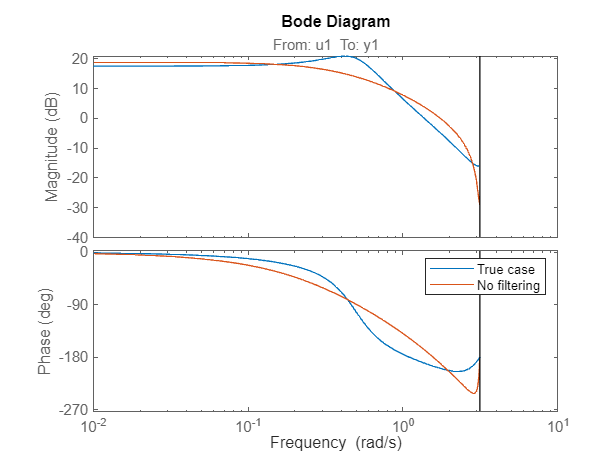

% Bode diagram
figure(2), bode(G0,mw),
legend("True case","No filtering")

It is now clear that there is a big error at low frequencies.

### 1.5. Checking step response

Actually there is a way to understand if the error is bigger at low frequencies in the time domain, but it is not as precise as in the frequency domain. We compare the step response of the original system and of the identified model.

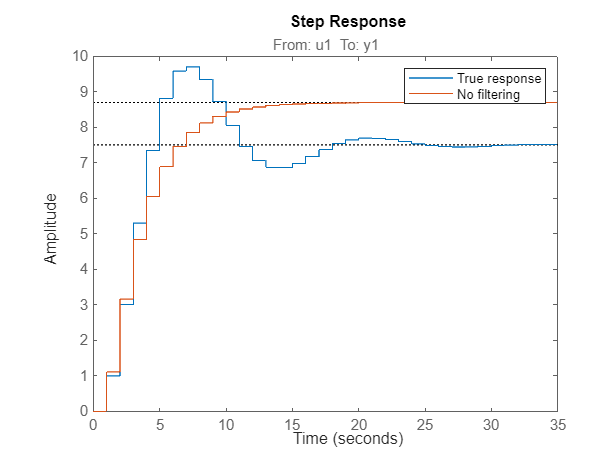

% Step response
figure(3), step(G0,mw),
legend("True response","No filtering")

We can see that the transient looks fine but at steady state there is a constant error. This means the error is bigger at low frequencies.

## 2. Identification with prefiltering

To avoid this problem and have a more uniformed error in the frequency domain, we can perform the so called prefiltering.

### 2.1. Choosing the filter

First thing we need to do is to choose the structure of the filter $L\left(z\right)$ to be used. Since we want to compensate the low-pass behaviour of the transfer function $W\left(z\right)$ of the noise, we consider the transfer function of the filter to be equal to the transfer function of the noise in order to perform a complete cancelation. Let us recall that ARX models are described by the following transfer functions:


$$G\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)},\;\;\;\;\;\;\;\;\;\;W\left(z\right)=\frac{1}{A\left(z\right)}$$


Of course we do not know the polynomial at the denominator of the transfer function of the noise but we have already computed an estimate of that polyonomial through the previous model, so we can use that estimate to build our filter.

% Estimated polynomial
Aes = mw.A;

To filter the input and the output we can use the command `filter` which will take as an input the numerator and the denominator of the transfer function of the filter to be used and the object to be filtered.

% Performing prefiltering
Uf = filter(1,Aes,U);
Yf = filter(1,Aes,Yw);

 Now that we have performed prefiltering, we can declare the `iddata` object to be used for identification.

% Dataset
Df = iddata(Yf,Uf,Ts);

### 2.2. Performing identification

Now we can train again the ARX(2,2) model in order to evaluate if the prefiltering has improved the identification.

% ARX(2,2) model
mf = arx(Df,[2,2,1]);

Then we can evaluate the behaviour of the model using the `compare` command.

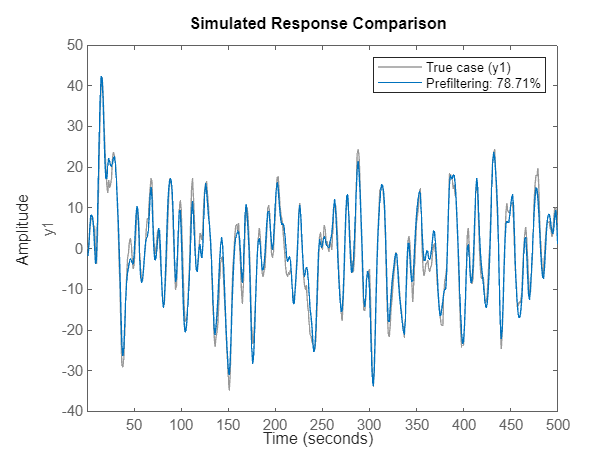

% Plotting results
figure(4), compare(Df,mf),
legend("True case","Prefiltering")

As we can see the results show a huge improvement with respect to the case in which we didn't perform prefiltering.

### 2.3. Checking Bode diagram

Let's also see what happens in the frequency domain by comparing the Bode diagrams of the real system and the identified model.

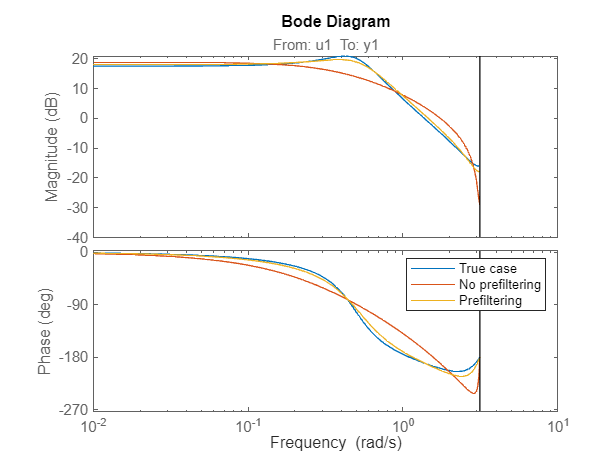

% Bode diagram
figure(5), bode(G0,mw,mf),
legend("True case","No prefiltering","Prefiltering")

As we can see the error at low frequencies are now mitigated.

### 2.4. Checking step response

Let's also take a look at the comparison between the step response of the real system and the step response of the identified model.

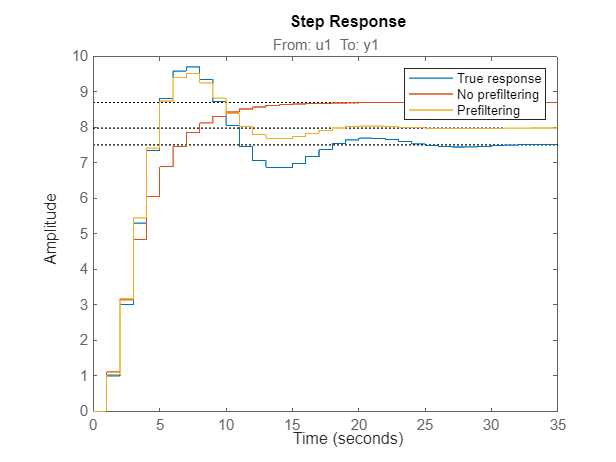

% Step response
figure(6), step(G0,mw,mf),
legend("True response","No prefiltering","Prefiltering")

As we can see also the step response now shows a smaller error at steady state, even though it is still not neglectable.

## 3. Repeating prefiltering

To furtherly improve the identifcation results, we can repeat again the prefiltering

### 3.1. Choosing the filter

The reason why performing prefiltering again will improve the results of the identification is because we can use a better estimate of the polynomials of the system in order to choose a better transfer function for the filter to be used.

% Estimated polynomial
Aes = mf.A;

To filter the input and the output we can use the command `filter` which will take as an input the numerator and the denominator of the transfer function of the filter to be used and the object to be filtered.

% Performing prefiltering
Uff = filter(1,Aes,U);
Yff = filter(1,Aes,Yw);

 Now that we have performed prefiltering, we can declare the `iddata` object to be used for identification.

% Dataset
Dff = iddata(Yff,Uff,Ts);

### 3.2. Performing identification

Now we can train again the ARX(2,2) model in order to evaluate if the prefiltering has improved the identification.

% ARX(2,2) model
mff = arx(Dff,[2,2,1]);

Then we can evaluate the behaviour of the model using the `compare` command.

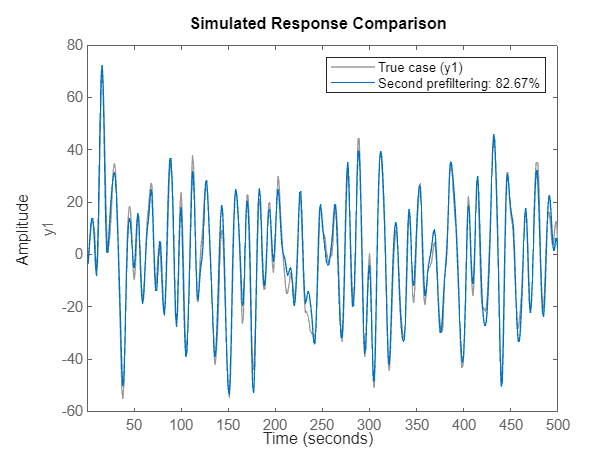

% Plotting results
figure(7), compare(Dff,mff)
legend("True case","Second prefiltering")

As we can see the results have furtherly improved since we considered a better estimate.

### 3.3. Checking Bode diagram

Let's also see what happens in the frequency domain by comparing the Bode diagrams of the real system and the identified model.

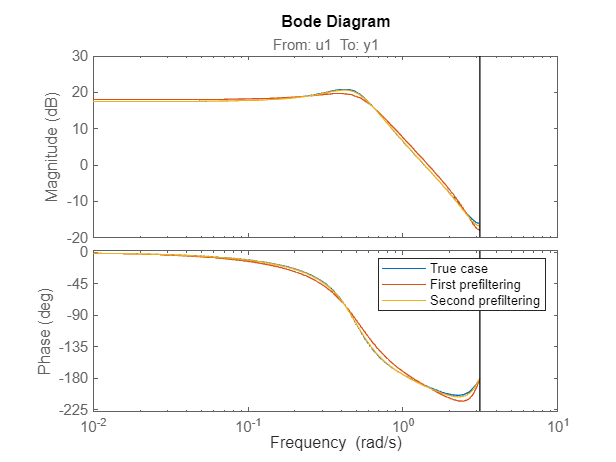

% Bode diagram
figure(8), bode(G0,mf,mff),
legend("True case","First prefiltering","Second prefiltering")

As we can see the Bode plots are now almost superimposable.

### 3.4. Checking step response

Let's also take a look at the comparison between the step response of the real system and the step response of the identified model.

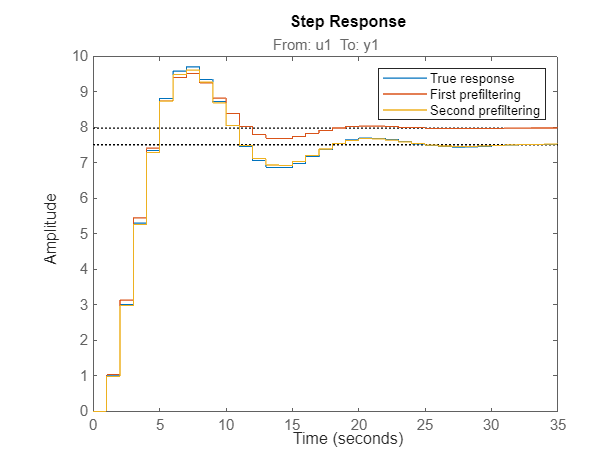

% Step response
figure(9), step(G0,mf,mff),
legend("True response","First prefiltering","Second prefiltering")

Now the step response shows a very small error at steady state.

### 3.5. Choosing the iterations

We may wonder how many times do we need to repeat the prefiltering. Actually, we perform prefiltering until there are no important improvements in the identification results. For this reason, we perform prefiltering again.

% Estimated polynomial
Aes = mff.A;

% Performing prefiltering
Ufff = filter(1,Aes,U);
Yfff = filter(1,Aes,Yw);

% Dataset
Dfff = iddata(Yfff,Ufff,Ts);

% ARX(2,2) model
mfff = arx(Dff,[2,2,1]);

Let's evaluate the behaviour of the model.

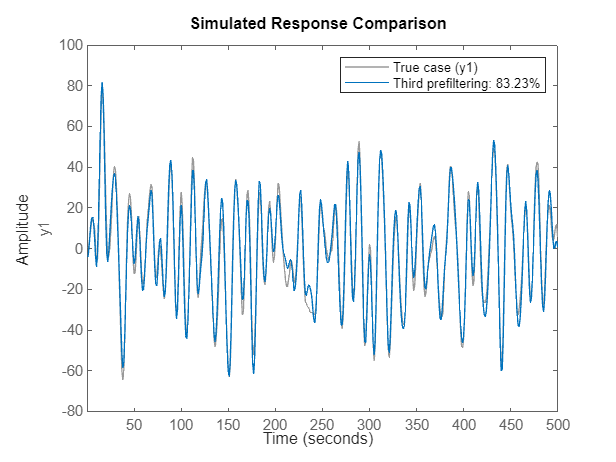

% Plotting results
figure(10), compare(Dfff,mfff)
legend("True case","Third prefiltering")

As we can see there is improvement in the fit after the further iteration. Let's evaluate the Bode diagrams.

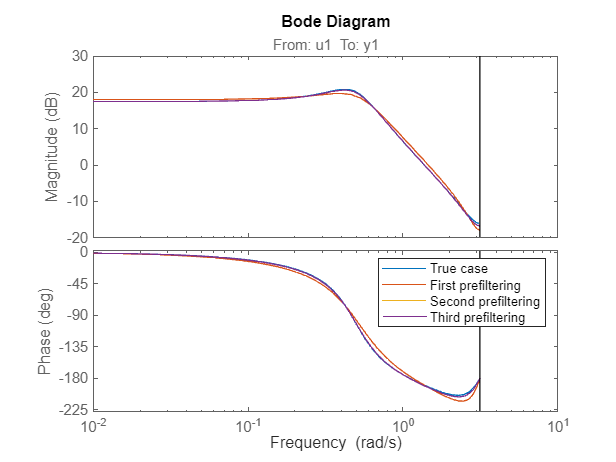

% Bode diagram
figure(11), bode(G0,mf,mff,mfff)
legend("True case","First prefiltering","Second prefiltering","Third prefiltering")

Even for the Bode diagrams there are no differences at all. Let's finally check the step response.

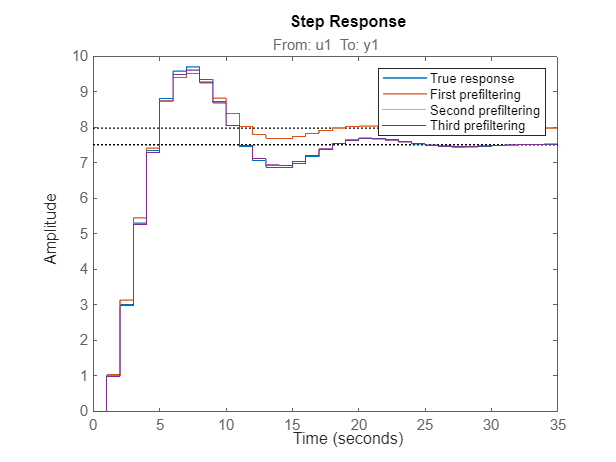

% Step response
figure(12), step(G0,mf,mff,mfff)
legend("True response","First prefiltering","Second prefiltering","Third prefiltering")

Since there is no improvement in terms of fit, of bode diagram and of step response, it means that it is useless to further perform prefiltering. The results were already at their best at the previous - and second - iteration of the prefiltering. 

## 4. Prefiltering with colorful noise

Until now we have considered the case of white noise. Let us now consider the case in which the system is affected by colorful noise. 

### 4.1. Defining colorful noise noise

We distinguish between broad-band colorful noise, where the noise is distributed in a wide band of frequencies, and narrow-band colorful noise, where instead the noise is distributed in a very short window of frequencies. Then we normalize the noise vectors considering a noise power of 10%, so a standard deviation of 0.1, and then we add them to the output vector.

% Broad-band colorful noise
cbb = filter(1,[1.0,-0.6],randn(N,1));

% Narrow-band colorful noise
cnb = filter(1,[1.000,-0.999],randn(N,1));

% Noise normalization
cbb = cbb/std(cbb)*std(Y0)*sqrt(0.1);
cnb = cnb/std(cnb)*std(Y0)*sqrt(0.1);


% Noisy outputs
Ybb = Y0 + cbb;
Ynb = Y0 + cnb;

Now that we have computed the output of the system under uncertainty, we can define our `iddata` objects.

% Datasets
Dbb = iddata(Ybb,U);
Dnb = iddata(Ynb,U);

### 4.2. Performing identification

In order to assess the effects of prefiltering in presence of colorful noise, we first need an estimate of the polynomials of the system. For this reason, we perform the identification using an ARX(2,2) model, so a model that belongs to the same family of the system.

% ARX(2,2) models
mbb = arx(Dbb,[2,2,1]);
mnb = arx(Dnb,[2,2,1]);

### 4.3. Performing prefiltering

After the first identification we have the rough estimates of the polynomials of the system.

% Estimated polynomial
Abb = mbb.A;
Anb = mnb.A;

Then we can perform prefiltering for both cases.

% Performing prefiltering
Ufbb = filter(1,Abb,U);
Ufnb = filter(1,Anb,U);
Yfbb = filter(1,Abb,Ybb);
Yfnb = filter(1,Anb,Ynb);

Now that we have performed prefiltering, we can declare the `iddata` objects to be used for identification.

% Datasets
Dfbb = iddata(Yfbb,Ufbb,Ts);
Dfnb = iddata(Yfnb,Ufnb,Ts);

Then we perform again the identification.

% ARX(2,2) models
mfbb = arx(Dfbb,[2,2,1]);
mfnb = arx(Dfnb,[2,2,1]);

### 4.4. Comparing results

For simplicity, let's first evaluate the step responses in case of broad-band colorful noise.

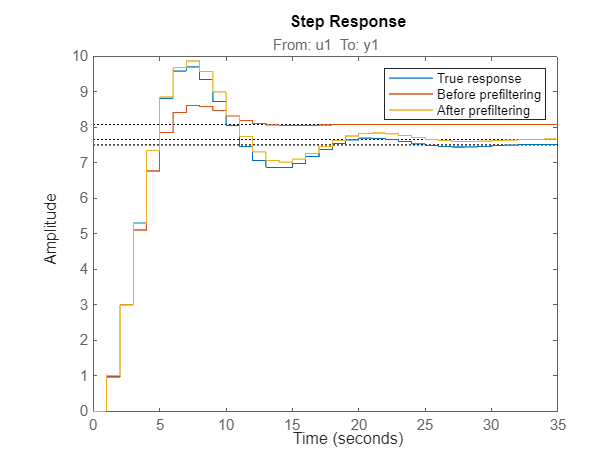

% Step responses in case of broad-band colorful noise
figure(13), step(G0,mbb,mfbb)
legend("True response","Before prefiltering","After prefiltering")

As we can see the results after prefiltering are better than the results before prefiltering in case of broad-band colorful noise.

Let's now evaluate the step responses in case of narrow-band colorful noise.

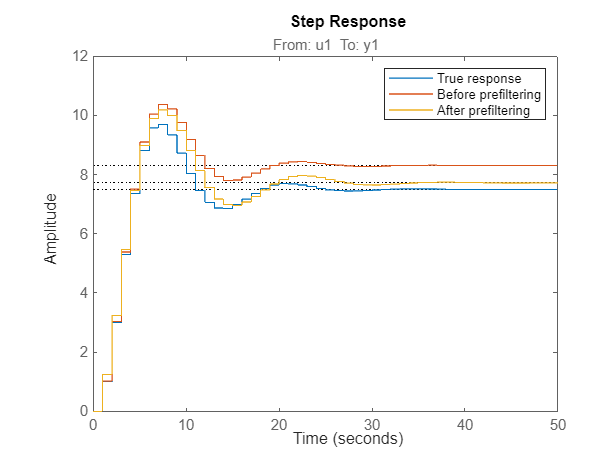

% Step responses in case of narrow-band colorful noise
figure(14), step(G0,mnb,mfnb)
legend("True response","Before prefiltering","After prefiltering")

In this case prefiltering has not improved the results, instead, it worsen the behaviour during the second peak and at steady state.

### 4.5. Understanding results

The reason why prefiltering is more effective on broad-band colorful noise compared to narrow-band colorful noise lies in the nature of the frequency spectrum of the noise. Broad-band noise provides more opportunities for the filter to attenuate noise across a wide range of frequencies, while the concentrated frequency components of narrow-band noise make it difficult to design a filter that can reduce noise without significantly distorting the signal, resulting in less effective noise reduction and potentially poorer performance.

It can be said that the more narrow the band of the colorful noise is, the less efficient is the prefilter. In fact, if the colorful noise has a narrow-band, making the optimization algorithm weighting more the low frequencies does not improve the estimation of the system. This happens because the noise model of the family model, in our case ARX, is not flexible enough to describe the behaviour of the real system belonging to the more generic Box-Jenkins family. In fact, with an ARX model we have:


$$W\left(z\right)=\frac{1}{A\left(z\right)}$$


so the only choice for the filter is:


$$L\left(z\right)=W\left(z\right)=\frac{1}{A\left(z\right)}$$


while in the Box-Jenkins family the noise model $W\left(z\right)$ does not depend to $A\left(z\right)$ at all:


$$W\left(z\right)=\frac{C\left(z\right)}{D\left(z\right)}$$
